close all
clear
clc

# 绘制各种曲面和线条

figure(1);

定义二维sinc函数，先生成xy平面上的均匀采样点，再转换为极坐标，sinc(模长)即为二维sinc函数

x=-3:0.3:3;
y=x;
[X,Y]=meshgrid(x,y);
[theat,R]=cart2pol(X,Y);
Z=sinc(R);

绘制peaks等高线

subplot(2,3,1);
contour(peaks(30),10); colorbar;
title('contour'); 

绘制二维sinc曲面的线条

subplot(2,3,2), hold on; 
title('plot3');     
plot3(X,Y,Z); grid on;
axis tight;
view([37.84 29.95])

绘制某函数的瀑布线

subplot(2,3,3), hold on, box on; 
title('waterfall'); 
waterfall(membrane(1)); 
axis tight;
view([-53 25])

绘制peaks的三维等高线

subplot(2,3,4), hold on, box on; 
title('contour3');  
contour3(peaks(30),25); 
axis tight;
view([-23 14])

绘制二维sinc的网格线

subplot(2,3,5), hold on, box on; 
title('mesh');      
mesh(X,Y,Z); 
axis tight;
view([234 23])

绘制二维sinc的网格线

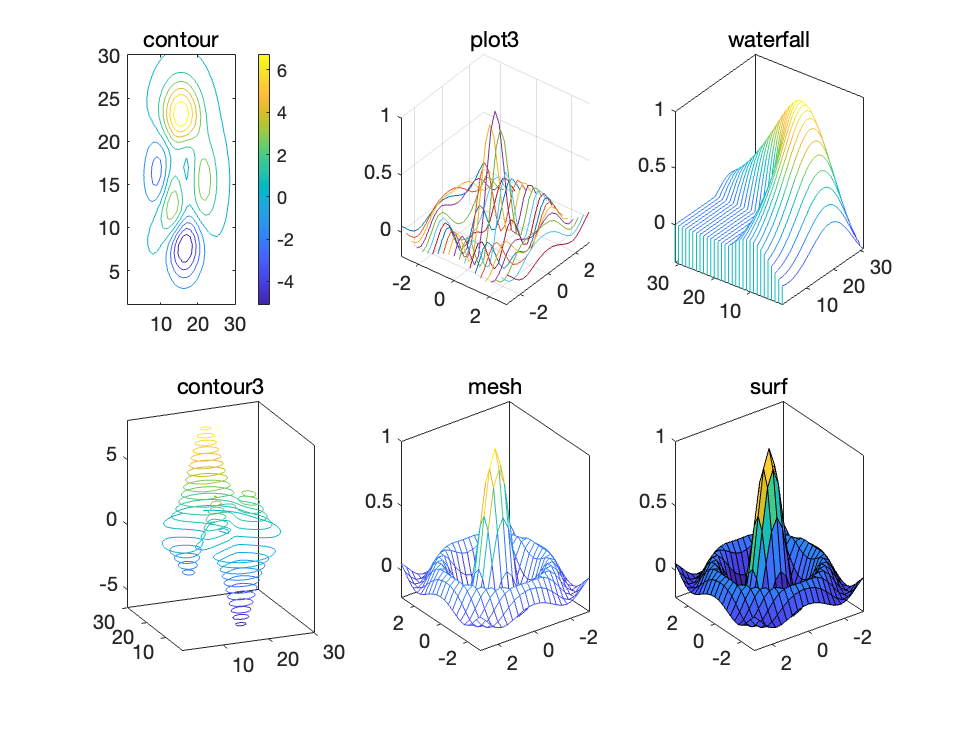

subplot(2,3,6), hold on, box on; 
title('surf');      
surf(X,Y,Z); 
axis tight;
view([234 23])

# 绘制各种数据图

生成数据矩阵

data = [10 2 3 5; 5 8 10 13; 9 7 6 1; 3 5 7 2; 4 7 5 3];
figure(2);

绘制柱状图

subplot(2,3,1), hold on, box on; 
title('bar');       
bar(data,'stacked');          
axis tight;

绘制三维柱状图

subplot(2,3,2), hold on, box on; 
title('bar3h');     
bar3h(data); 
axis tight;
view(143,15);

绘制直方图

subplot(2,3,3), hold on, box on; 
title('histogram'); 
hist(randn(1000,3));
axis tight;

绘制面积图

subplot(2,3,4), hold on, box on; 
title('area');      
area(data);
axis tight;

绘制三维饼图

subplot(2,3,5), hold on, box on; 
title('3Dpie');     
pie3(sum(data), [ 0 0 1 0]);
axis tight;
view(20,60);

绘制极坐标直方图

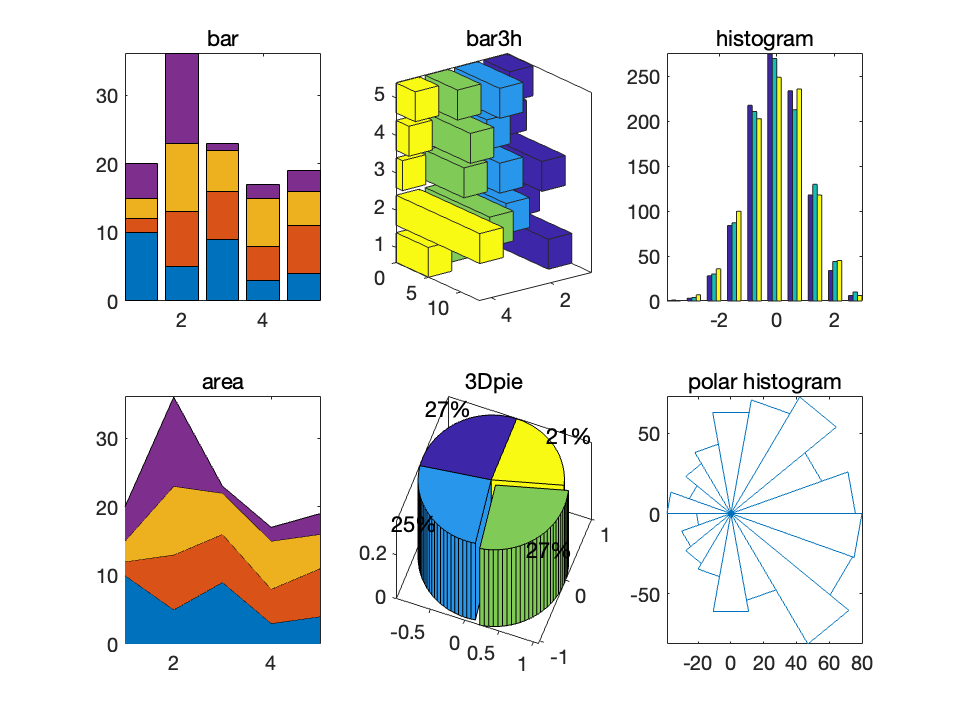

subplot(2,3,6), hold on, box on; 
title('polar histogram'); 
rose(5/3*randn(1000,1),18);
axis tight;

# 绘制各种其他图

figure(3);

绘制一个系统的冲激响应波形及其零阶抽样保持

t = 0:0.1:10;
z = impulse(1,[1 1 1],t);
subplot(2,3,1), hold on, box on;
title('stairs');
stairs(t(1:5:end),z(1:5:end));
plot(t,z,'r'); 
plot([0 t(end)],[ 0 0],'k:');

绘制矩形脉冲的傅里叶变换，在单位圆上，类似sinc函数

theta = 2*pi*(0:63)/64;
x=cos(theta); 
y=sin(theta); 
z=abs(fft(ones(10,1),64));
subplot(2,3,2), hold on, box on;
title('stem3'); 
stem3(x,y,z');
view(117,20);

绘制peaks的梯度和等高线

[x y z] = peaks(-2:0.25:2);
[U V] = gradient(z,0.25);
subplot(2,3,3), hold on, box on;
title('contour & quiver'); 
set(gca,'XLim',[-2 2],'YLim',[-2 2]);
contour(x,y,z,10); 
quiver(x,y,U,V);

绘制螺旋线，rho随theta线性增长

theta = 0:0.1:4*pi;
[x,y] = pol2cart(theta(1:5:end),theta(1:5:end));
subplot(2,3,4), hold on, box on;
title('polar'); 
polar(theta, theta);

绘制罗盘线

subplot(2,3,5), hold on, box on;
title('compass'); 
compass(x,y);
axis tight;

绘制羽毛线

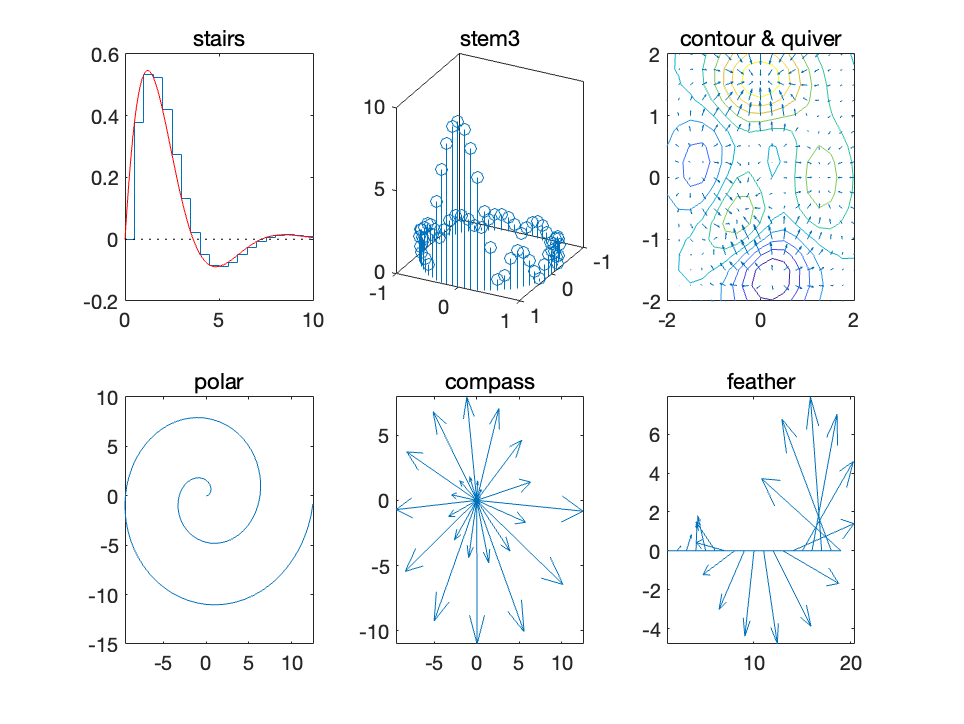

subplot(2,3,6), hold on, box on;
title('feather'); 
feather(x(1:19),y(1:19));
axis tight;